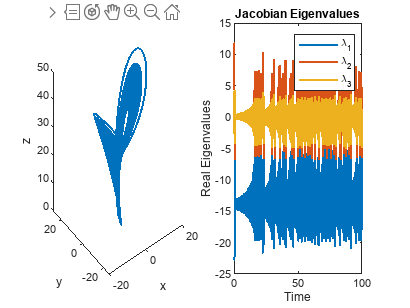

% Lorenz system parameters
sigma = 10;
beta = 8/3;
rho = 28;

% Lorenz system equations
dxdt = @(t,x) [sigma*(x(2)-x(1)); x(1)*(rho-x(3))-x(2); x(1)*x(2)-beta*x(3)];

% Initial conditions
x0 = [0.1; 0.1; 0.1];

% Time interval
tspan = [0 100];

% Solve the ODE using MATLAB's ode45 solver
[t,x] = ode45(dxdt, tspan, x0);

% Calculate the Jacobian matrix
n = length(t);
J = zeros(3,3,n);
for i = 1:n
    J(:,:,i) = [ -sigma     sigma      0;
                rho-x(i,3) -1         -x(i,1);
                x(i,2)     x(i,1)     -beta ];
end

% Calculate the Lyapunov exponents
LE = zeros(3,1);
v = eye(3);
for i = 1:n
    Jv = J(:,:,i)*v;
    [Q,R] = qr(Jv);
    v = Q;
    LE = LE + log(abs(diag(R)));
end
LE = LE/n;

% Plot the Lorenz system and the Jacobian eigenvalues
figure;
subplot(1,2,1);
plot3(x(:,1), x(:,2), x(:,3), 'LineWidth', 1.5);
xlabel('x');
ylabel('y');
zlabel('z');
title('Lorenz System');

subplot(1,2,2);
eigvals = zeros(3,n);
for i = 1:n
    eigvals(:,i) = eig(J(:,:,i));
end
plot(t, real(eigvals(1,:)), 'LineWidth', 1.5);
hold on;
plot(t, real(eigvals(2,:)), 'LineWidth', 1.5);
plot(t, real(eigvals(3,:)), 'LineWidth', 1.5);
xlabel('Time');
ylabel('Real Eigenvalues');
title('Jacobian Eigenvalues');
legend('\lambda_1', '\lambda_2', '\lambda_3');


% Print the Lyapunov exponents
disp('Lyapunov exponents:');

Lyapunov exponents:


disp(LE);

    2.6281
    1.9671
    1.6195

